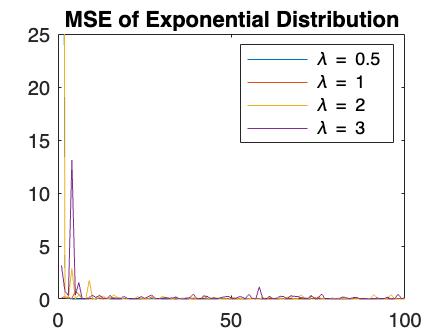

clc
clear 
close all


%% Question 1


sample = 100; 
lambda = [0.5, 1, 2, 3];
sigma = [0.5, 1, 2, 3, 4];

% preallocate exp
mse_exp = zeros(sample, length(lambda));
bias_exp = zeros(sample, length(lambda));
var_exp = zeros(sample, length(lambda));


for i = 1:length(lambda)
    for n = 1:sample
        % Generate exponential random variables
        exp_samples = exprnd(1/lambda(i), n, 1);
        lambda_ml = 1/mean(exp_samples);
        
        % Compute MSE, bias, and variance for exponential distribution
        mse_exp(n, i) = (lambda_ml - lambda(i))^2;
        bias_exp(n, i) = lambda_ml - lambda(i);
        var_exp(n, i) = var(exp_samples) / n;
    end
end

figure;
plot(1:sample, mse_exp);
title('MSE of Exponential Distribution');
legend(arrayfun(@(x) ['\lambda = ' num2str(x)], lambda, 'UniformOutput', false));
xlim([0, 100]);
ylim([0, 25]);

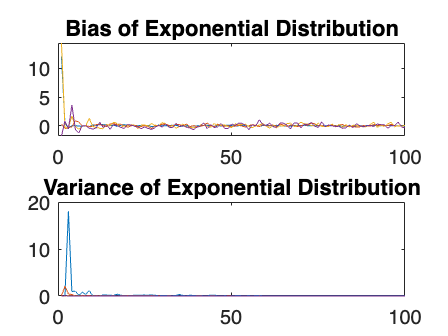



figure
subplot(2, 1, 1);
plot(1:sample, bias_exp);
title('Bias of Exponential Distribution');


subplot(2, 1, 2);
plot(1:sample, var_exp);
title('Variance of Exponential Distribution');

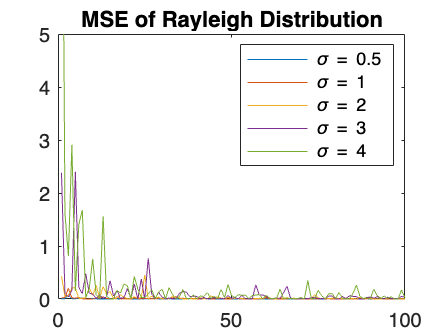



% preallocate ray
mse_ray = zeros(sample, length(sigma));
bias_ray = zeros(sample, length(sigma));
var_ray = zeros(sample, length(sigma));


for i = 1:length(sigma)
    for n = 1:sample
        % Generate Rayleigh random variables
        ray_samples = raylrnd(sigma(i), n, 1);
        sigma_ml = sqrt(mean(ray_samples.^2) / 2);
        
        % Compute MSE, bias, and variance for Rayleigh distribution
        mse_ray(n, i) = (sigma_ml - sigma(i))^2;
        bias_ray(n, i) = sigma_ml - sigma(i);
        var_ray(n, i) = var(ray_samples) / (2*n);
    end
end

figure;
plot(1:sample, mse_ray);
title('MSE of Rayleigh Distribution');
legend(arrayfun(@(x) ['\sigma = ' num2str(x)], sigma, 'UniformOutput', false));
xlim([0, 100]);
ylim([0, 5]);

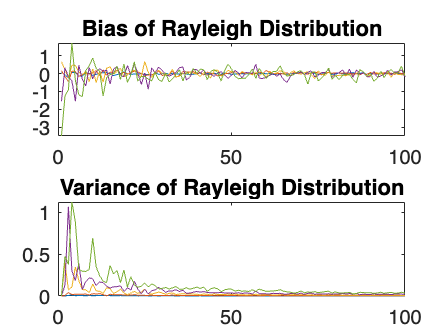



figure
subplot(2, 1, 1);
plot(1:sample, bias_ray);
title('Bias of Rayleigh Distribution');

subplot(2, 1, 2);
plot(1:sample, var_ray);
title('Variance of Rayleigh Distribution');



%% Question 2

load('data.mat');  

% Compute MLE for the exponential distribution parameter (lambda)
lambda_ml = 1/mean(data)

lambda_ml = 7.7948


% Compute MLE for the Rayleigh distribution parameter (sigma)
sigma_ml = sqrt(mean(data.^2)/2)

sigma_ml = 0.1016


% Compute the log-likelihoods for both distributions
log_likelihood_exp = sum(log(lambda_ml * exp(-lambda_ml * data)))

log_likelihood_exp = 1.0535e+03

log_likelihood_ray = sum(log((data/sigma_ml^2) .* exp(-data.^2/(2*sigma_ml^2))))

log_likelihood_ray = 1.3655e+03


% Compare the log-likelihoods
 disp('The distribution with the higher log-likelihood value is considered a better fit for the data, so the data is more likely drawn from a Rayleigh distribution.');

The distribution with the higher log-likelihood value is considered a better fit for the data, so the data is more likely drawn from a Rayleigh distribution.
